# **Esercitazione 1 - ECG**

Obiettivo 1: implementare una funzione per identificare i picchi R all'interno di ciascun segnale.

Caricamento del dato nel workspace utilizzando la funzione `load().`

load("data.mat")

Suddivisione del segnale in finestre continue con stessa lunghezza pari a pochi secondi (scelti arbitrareamente) e quindi rimozione del trend lineare tramite l'uso della funzione detrend.

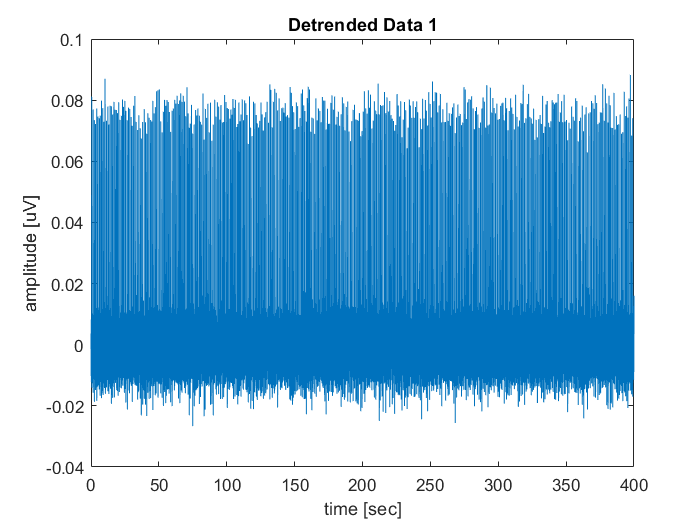

%lunghezza k delle finestre 
k = 1; % [s]

%suddivisione dei segnali
data1 = reshape(data1,fs*k,[]);
data1NoTrend = detrend(data1);

data2 = reshape(data2,fs*k,[]);
data2NoTrend = detrend(data2);

%visualizzazione del risultato ottenuto
data1NoTrend = data1NoTrend(:);

data2NoTrend = data2NoTrend(:);

figure, plot(time,data1NoTrend)
title('Detrended Data 1')
ylabel('amplitude [uV]')
xlabel('time [sec]')

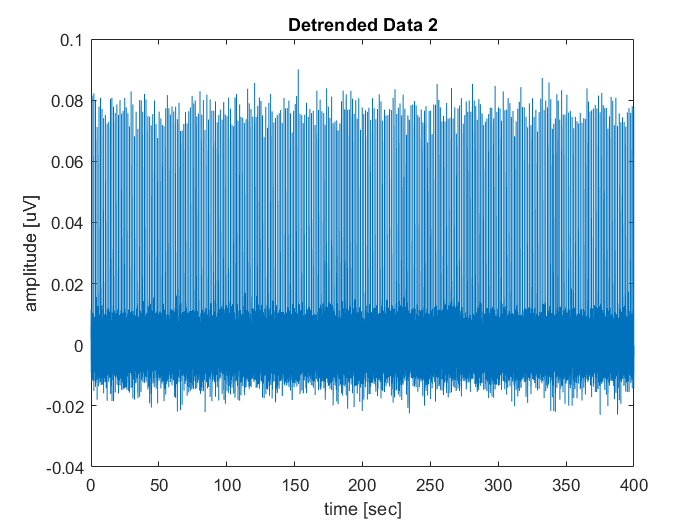

figure, plot(time,data2NoTrend)
title('Detrended Data 2')
ylabel('amplitude [uV]')
xlabel('time [sec]')

Identificazione picchi R tramite una soglia ottima.

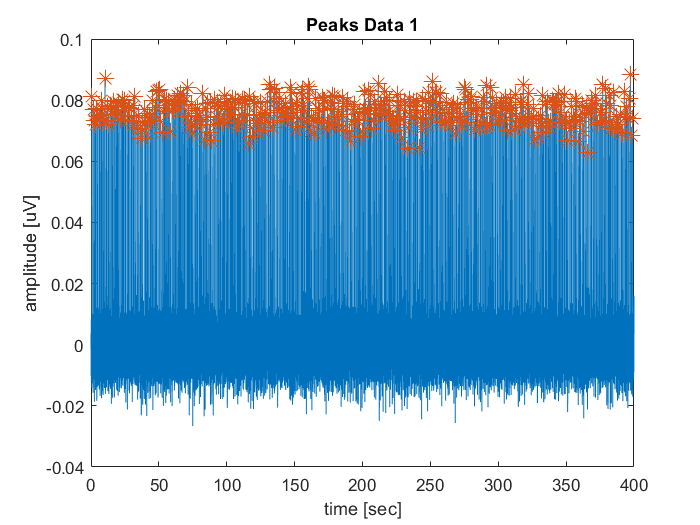

%Utilizzo funzione per il calcolo della soglia ottima
thr=find_thr(data1NoTrend,7.5);
[values1,MaxInd1] = findpeaks(data1NoTrend,fs,'MinPeakHeight',  thr);

figure, plot(time, data1NoTrend)
title('Peaks Data 1')
ylabel('amplitude [uV]')
xlabel('time [sec]')

hold on
plot(MaxInd1,values1,'*','MarkerSize',10)
hold off

%scatter(time(MaxInd),data1NoTrend(MaxInd), [], "red", "filled")]

thr=find_thr(data2NoTrend,7.5)

thr = 0.0483

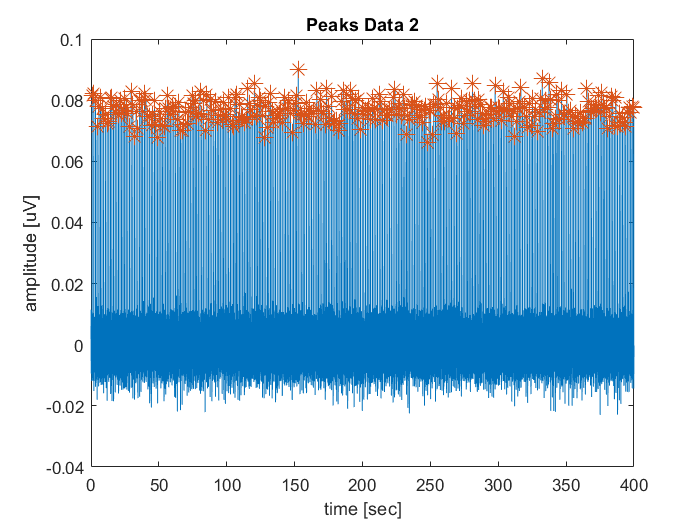

[values2,MaxInd2] = findpeaks(data2NoTrend,fs,'MinPeakHeight',  thr);

figure,plot(time, data2NoTrend)
title('Peaks Data 2')
ylabel('amplitude [uV]')
xlabel('time [sec]')

hold on
plot(MaxInd2,values2,'*','MarkerSize',10)
hold off

Obiettivo 2: implementare una funzione compute_heart_rate per stimare la frequenza del battito cardiaco.

%heart_rate1 = compute_heart_rate(MaxInd1, data1NoTrend, freq)
freq=fs

freq = int64
1000

bpm_1=length(MaxInd1)/ ( (length(data1NoTrend)/freq) / 60  )

bpm_1 = int64
62

bpm_2=length(MaxInd2)/( (length(data1NoTrend)/freq) / 60  )

bpm_2 = int64
47


%da mettere function
%function heart_rate=compute_heart_rate(peaks, dataNoTrend, freq)
 %   heart_rate=length(peaks)/(length(dataNoTrend)/freq)*60;
%end

Obiettivo 3: implementare una funzione per il calcolo della durata del complezzo QRS e per la visualizzazione del complesso QRS medio.

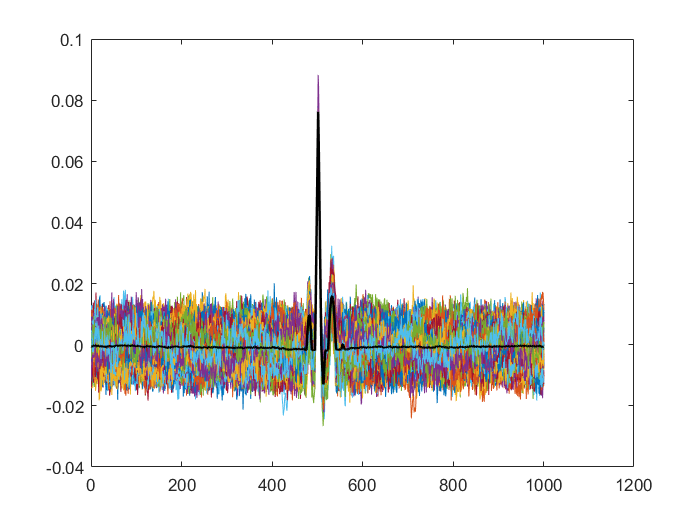


dist_RR1=MaxInd1(2:end)-MaxInd1(1:end-1);
dist_RR2=MaxInd2(2:end)-MaxInd2(1:end-1);




dist_media1=round(mean(dist_RR1));


meta_dist1=dist_media1/2;
 
%matrice che contiene i singoli tracciati [numero campioni x numero battiti]
solo_tracciato1=zeros(dist_media1*fs+1, length(MaxInd1));

figure 

for j=1:length(MaxInd1) 
    solo_tracciato1 (:, j ) = data1NoTrend ( fs*(MaxInd1(j)-meta_dist1) : fs*(MaxInd1(j)+meta_dist1) ) ;   
    plot(solo_tracciato1 (:, j ))
    hold on
end


solo_tracciato1=solo_tracciato1';
solo_medio1=mean(solo_tracciato1);

plot(solo_medio1, "k", "LineWidth", 1.5);
hold off

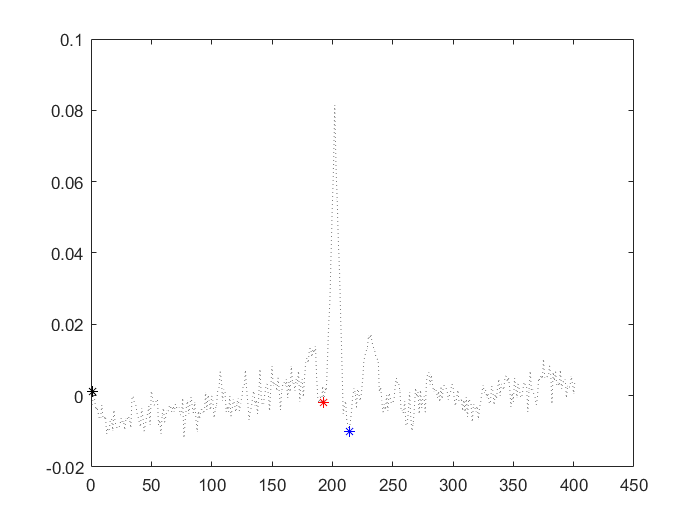

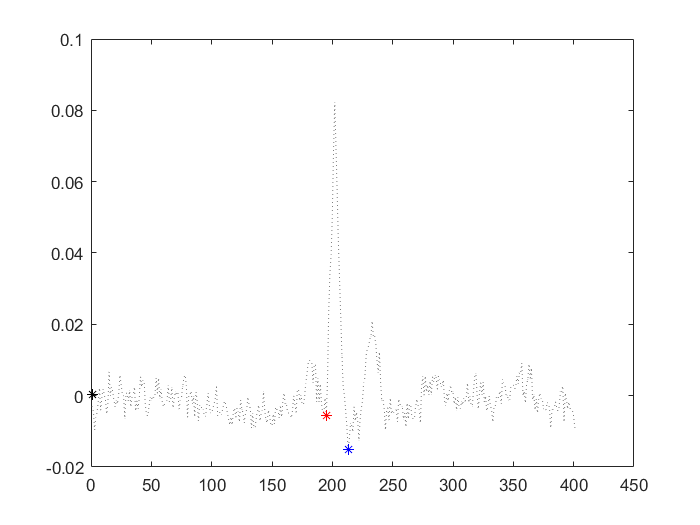

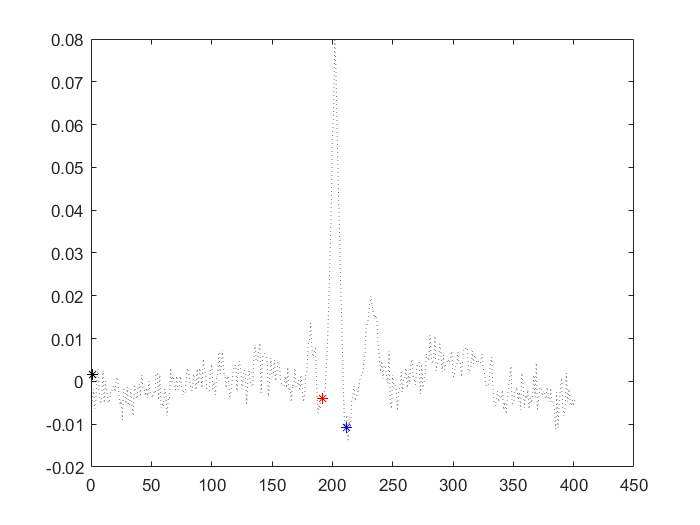

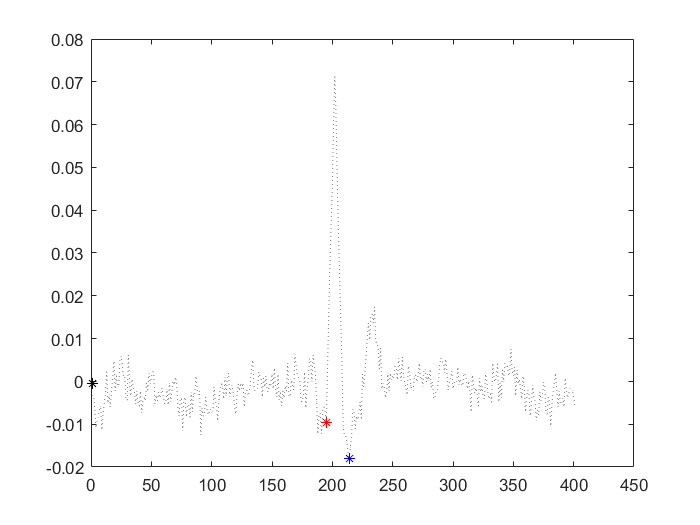

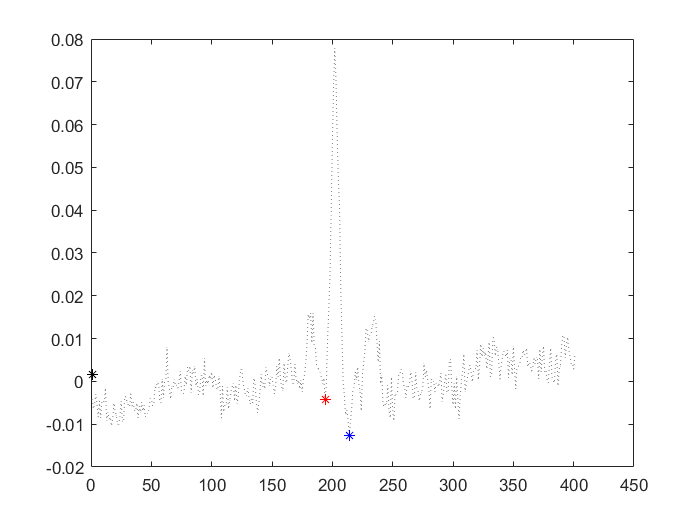

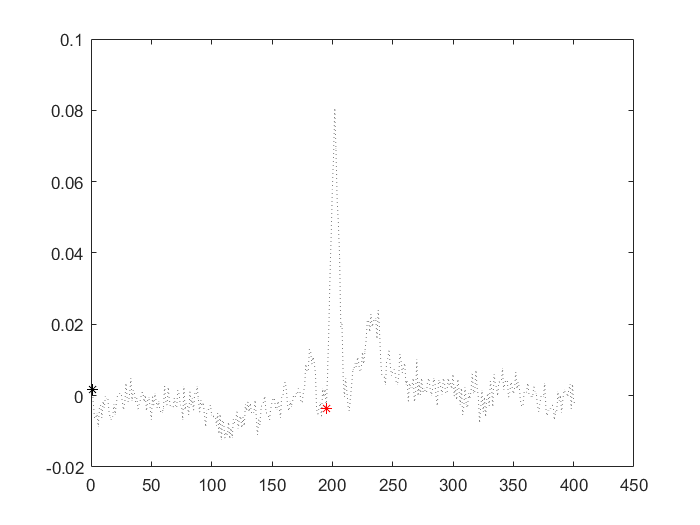

Index exceeds the number of array elements (0).


dist_media2=round(mean(dist_RR2));

meta_dist2=dist_media2/5;

solo_tracciato2=zeros(length(MaxInd2), fs*meta_dist2*2+1);

xQ = zeros (length(MaxInd2), 1) ;
xS = zeros (length(MaxInd2), 1) ;

figure 


% for j=1:length(MaxInd2)
%     solo_tracciato2(j,:)=data2NoTrend(fs*(MaxInd2(j)-meta_dist2) : fs*(MaxInd2(j)+meta_dist2));
%     
%     plot(  solo_tracciato2(j,:) , ":" , "Color",'#808080')
%     hold on
% end

 

%qrs= qrs_duration (solo_tracciato2);

 z=zeros (1, length(MaxInd2));
 zzz=zeros (1, length(MaxInd2));
 
 w=zeros (1, length(MaxInd2));
 www=zeros (1, length(MaxInd2));
 

 for j=1: round (length(MaxInd2) / 50)
     
     figure
     
     
    solo_tracciato2(j,:)=data2NoTrend(fs*(MaxInd2(j)-meta_dist2) : fs*(MaxInd2(j)+meta_dist2));
    
    plot(  solo_tracciato2(j,:) , ":" , "Color",'#808080')
    
     
     
     thr2=find_thr( - solo_tracciato2 ( j , :) , -5 );
     
     [Qj, xQj] = findpeaks ( - solo_tracciato2 ( j , 1: round( length(solo_tracciato2)/ 2 )) , 'MinPeakHeight',  0   );
    
     z(j)= -Qj(end);
     zzz(j)= xQj(end);
    
     hold on
     plot(xQj (end) , z(j), '*' , 'Color' , 'r')
     
     hold on
     plot(    mean( solo_tracciato2 (j, : ) )  ,'*' , 'Color' , 'k'     )
     
     
     thr2=find_thr(  solo_tracciato2 ( j , :) , -1 );
    
     [Sj, xSj] = findpeaks ( - solo_tracciato2 ( j ,  round ( length(solo_tracciato2)/ 2 ): end ) , 'MinPeakHeight',   - thr2 );
     
     w(j)= -Sj(1);
     www(j)= xSj(1);
     
     hold on
     plot(xSj (1) + length(solo_tracciato2)/ 2 , w(j), '*' , 'Color' , 'b') 
     
     hold off
       
 end

%     NON VIENE UNA MINCHIA
 
mean(zzz)
mean(z)


hold on
plot(mean(zzz), mean(z), '*', 'color' , 'g')

mean(www)
mean(w)

hold on
plot(mean(www)+ length(solo_tracciato2)/2 , mean(w), '*', 'color' , 'g')


solo_medio2=mean(solo_tracciato2);


plot(solo_medio2, "k", "LineWidth", 1.5);
hold off

Obiettivo 4: implementare una funzione per la stima della densità di probabilità delle variabili derivate da ECG per descrivere i ritmi cardiaci.

...

Istogramma delle variabili derivate dall'ECG per entrambi i ritmi cardiaci.